C = 354 * 10^(-6)

C = 3.5400e-04



t = linspace(0, 3);

%y_ir = sign(t + 0.1) / C
y_sr = t / C

y_sr = 1.0e+03 *

         0    0.0856    0.1712    0.2568    0.3424    0.4280    0.5136    0.5992    0.6848    0.7704    0.8560    0.9416    1.0272    1.1128    1.1984    1.2840    1.3696    1.4552    1.5408    1.6264    1.7120    1.7976    1.8832    1.9688    2.0544    2.1400    2.2256    2.3112    2.3968    2.4825    2.5681    2.6537    2.7393    2.8249    2.9105    2.9961    3.0817    3.1673    3.2529    3.3385    3.4241    3.5097    3.5953    3.6809    3.7665    3.8521    3.9377    4.0233    4.1089    4.1945




num_i = [1];
den_i = [C 0];
sys_i = tf(num_i, den_i);
%{
plot(t, y_ir, 'c', LineWidth=1.5)
hold on
impulse(sys_i, 'k--')
legend('y_{i.r.} - аналитика', 'y_{i.r.} - симуляция')
title('Весовая функция для конденсатора')
grid()
ylabel("f(t)")
xlabel('t')
hold off
%}
num_s = [1];
den_s = [C 0 0];
sys_s = tf(num_s, den_s);
%{
plot(t, y_sr, 'c', LineWidth=1.5)
hold on
impulse(sys_s, 'k--')
legend('y_{s.r.} - аналитика', 'y_{s.r.} - симуляция')
title('Переходная функция для конденсатора')
grid()
ylabel("f(t)")
xlabel('t')
xlim([0 0.2])
hold off
%}

w = linspace(0, 50)

w =          0    0.5051    1.0101    1.5152    2.0202    2.5253    3.0303    3.5354    4.0404    4.5455    5.0505    5.5556    6.0606    6.5657    7.0707    7.5758    8.0808    8.5859    9.0909    9.5960   10.1010   10.6061   11.1111   11.6162   12.1212   12.6263   13.1313   13.6364   14.1414   14.6465   15.1515   15.6566   16.1616   16.6667   17.1717   17.6768   18.1818   18.6869   19.1919   19.6970   20.2020   20.7071   21.2121   21.7172   22.2222   22.7273   23.2323   23.7374   24.2424   24.7475


%{
ach = 1 ./ (C * w)
figure('Position', [1000 0 800 450])
plot(w, ach, LineWidth=1.5)

grid("on")
ylabel('A')
xlabel('\omega, rad/s')
legend('АЧХ')
ylim([0 5000])
title('Амплитудно-частотная характеристика')
%}

%{
ph1 = atan2(-1 ./ (C * w), 0) * 180 / pi
figure('Position', [1000 0 800 450])

plot(w, ph1, 'LineWidth', 1.5,'DisplayName', 'ФЧХ')
title('Фазово-частотная характеристика')
legend()
ylabel('φ, degrees')
xlabel('ω, rad / s')
grid("on")
%}

figure('Position', [1000 0 800 450])
ops = bodeoptions;
ops.Title.String = 'ЛАФЧХ'

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.Title.FontSize = 15

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.XLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

ops.YLabel.FontSize = 12

ops =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
      

   
h = bodeplot(sys_i, 'c', ops)


h =

	resppack.bodeplot



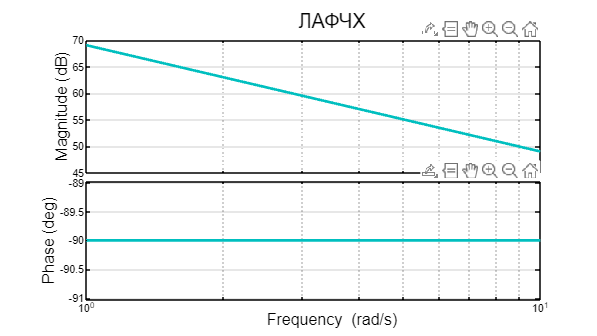

grid on;
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth